Az első feladatban készítek egy 512 pontban mintavételezett 2 Hz-es szinusz függvényt 20 dB-es SNR-val ($f_s =1000\;\textrm{Hz}$). Ezt egy x jelnek tekintem amin diszkrét wavelet-transzformációt !végzek a Haar-wavelet segítségével - három felbontási szintet használok. Az így kapott transzformáltat ábrázolom, majd zajszűrést végzek a wthcoef parancs segítségével. 

x=sig_noise(2,20,512)

x =    -0.2587    0.1813    0.3061    1.2407    1.2633    1.7998    3.0011    2.6201    0.2877   -0.5843    2.8200    0.2555    2.3306    2.4718    4.8355    2.7107    2.4438    3.3576    3.5378    3.5318    3.0223    2.5769    4.2839    2.7919    3.2693    5.7987    4.2139    4.6571    5.8610    4.8241    6.3158    5.1028    6.6212    6.3974    5.7138    5.2189    5.1983    6.1272    6.1140    6.2973    7.8422    6.7127    8.3046    6.7787    8.4312    7.0835    7.9282    8.8670    7.6258    7.7436


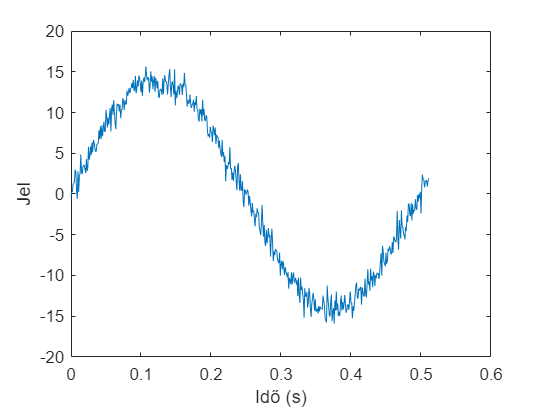

fs=1000;
Ts=1/fs;
N=length(x);
time=[0:N-1]*Ts;
x(200)=x(200);
figure
plot(time,x)
xlabel('Idő (s)')
ylabel('Jel')

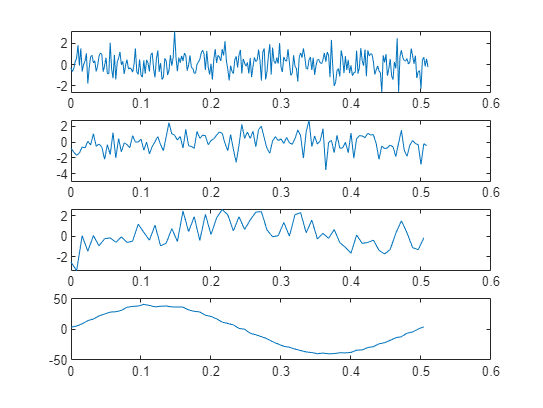


[c,l]=wavedec(x,3,'haar');

subplot(4,1,1)
plot(2*(0:l(end)/2-1)/1000,c(l(1)+l(2)+l(3)+1:l(1)+l(2)+l(3)+l(4)))

subplot(4,1,2)
plot(4*(0:l(end)/4-1)/1000,c(l(1)+l(2)+1:l(1)+l(2)+l(3)))

subplot(4,1,3)
plot(8*(0:l(end)/8-1)/1000,c(l(1)+1:l(1)+l(2)))

subplot(4,1,4)
plot(8*(0:l(end)/8-1)/1000,c(1:l(1)))


c_mod=wthcoef('d',c,l,[1,2,3],[100,100,100]) % első szinthez nyúlok hozzá és 100 %-át elhagyom.

c_mod =     3.5899    5.3483    9.0319   14.1572   16.8603   21.9020   25.0631   28.1843   28.7302   30.9982   36.0800   37.5223   38.0459   40.7034   39.0213   36.7471   37.6601   38.1971   36.5907   36.5699   36.3138   31.7085   29.4097   28.3683   23.0872   20.9905   17.1934   11.7003    9.6281    7.0434    1.5901    0.0746   -6.4255   -8.9930  -12.0717  -15.3058  -20.3395  -24.1453  -27.8169  -29.3948  -32.2562  -34.7041  -37.0151  -37.9957  -39.9634  -38.8634  -40.0349  -39.7568  -38.3790  -38.4767


y=waverec(c_mod,l,'haar')

y =     1.2692    1.2692    1.2692    1.2692    1.2692    1.2692    1.2692    1.2692    1.8909    1.8909    1.8909    1.8909    1.8909    1.8909    1.8909    1.8909    3.1933    3.1933    3.1933    3.1933    3.1933    3.1933    3.1933    3.1933    5.0053    5.0053    5.0053    5.0053    5.0053    5.0053    5.0053    5.0053    5.9610    5.9610    5.9610    5.9610    5.9610    5.9610    5.9610    5.9610    7.7435    7.7435    7.7435    7.7435    7.7435    7.7435    7.7435    7.7435    8.8612    8.8612


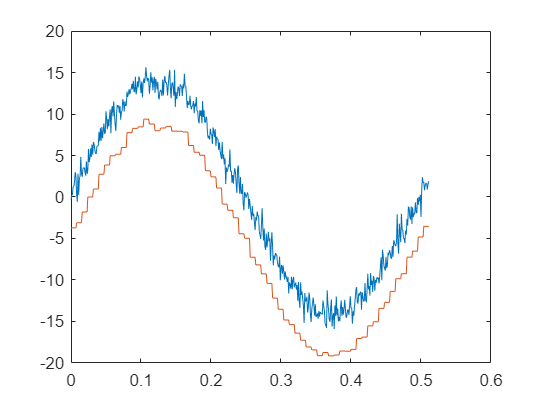

figure
plot(time,x,time,y-5) % Lejjebb toljuk 5-tel, hogy jobban lehessen látni.

A második feladatban előállítok egy olyan jelet, amelynek frekvenciája 1 másodperc alatt 100 Hz-ről 500 Hz-re nő, majd egy spectorgram-on ábrázolom ezt. Alkalmazok továbbá egy 32 elemű téglalap ablakot 50% átfedéssel - $f_s =1024$ Hz és $N=1024\ldotp$ 

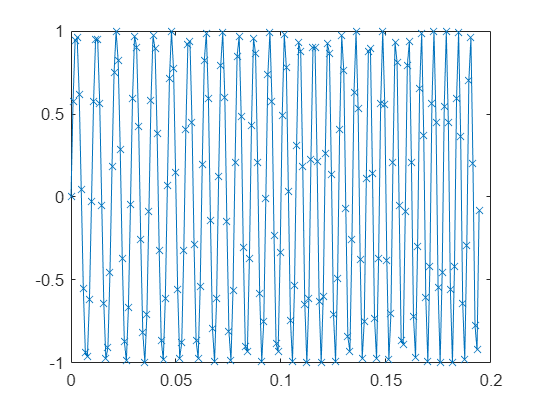

N = 1024;
fs = 1024; 
Ts=1/fs;
f1 = 100; 
f2 = 500; 
wl = 32; % ablakvektor elemszáma
t = (0:N-1)*Ts; 

x = sin(2*pi*(t.^2*(f2-f1)/2/1+f1*t)); 

sound(x,1024)

plot(t(1:200),x(1:200),'x-') % A jel elejének ábrázolása (az átláthatóság kedvéért)

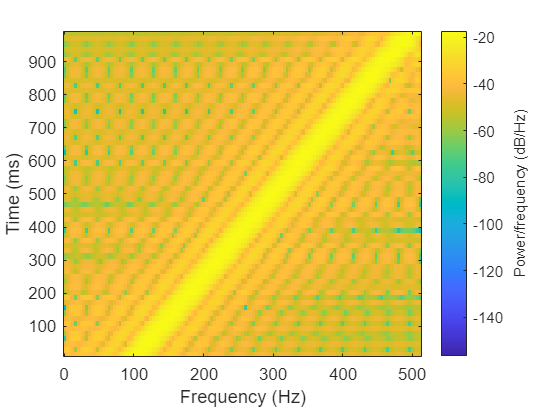


spectrogram(x,window(@rectwin,wl),wl/2,256,fs) % a spectrogram parancs hatása

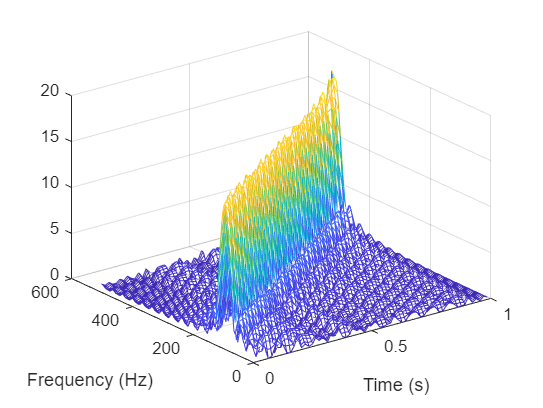


[S,frek,ido]=spectrogram(x,window(@rectwin,wl),wl/2,256,fs); % ábrázolás kétváltozós függvényként

mesh(ido,frek,abs(S)); 
xlabel('Time (s)')
ylabel('Frequency (Hz)')

A harmadik feladatban a [neural_data.mat](https://anal.math.bme.hu/sites/anal.math.bme.hu/files/users/rhorvath/Targyhonlapokhoz/BevMatlab/neural_data.mat) adaton fogok keresztkorrelációt számolni. Az adat két jelet tartalmaz, x és y, melyeket két különböző neuron esetén detektáltak az agyban 0.2 ms mintavételezési idővel. A két jel közti késést a neuronok távolsága okozza. Ábrázolom a jeleket és meghatározom a késés idejét keresztkorreláció segítségével.

load neural_data.mat
whos('-file','neural_data.mat')
Ts=0.0002
N=length(x)
time=[0:N-1]*Ts;

plot(time,x,'b-',time,y,'r-')
legend('x','y')

[xc,lags]=xcorr(x,y)
plot(Ts*lags,xc)
[max_corr,max_pos]=max(xc)
lags(max_pos)*Ts

A negyedik feladatban  egy sávszűrőt alkalmazok az [eeg21.mat](https://anal.math.bme.hu/sites/anal.math.bme.hu/files/users/rhorvath/Targyhonlapokhoz/BevMatlab/eeg21.mat) fájlban található EEG jelen ($f_s =50\;\textrm{Hz}$). A sávszűrő alsó vágási frekvenciája 3 Hz,  a felső 6 Hz. A szűréshez alkalmazom a Blackman–Harris ablakot, továbbá megadom a konvolúcióhoz szükséges impulzusválasz vektor hosszát - 129. 

load eeg21.mat 

Error using load
Unable to find file or directory 'eeg21.mat'.

whos('-file','eeg21.mat')
N=length(eeg)
fs=50;
Ts=1/fs;
time=(0:N-1)*Ts;
figure
plot(time,eeg)  % A jel időbeli lefolyása
xlabel('Idő (s)')
ylabel('Jel')

% Szürő tervezése
szuro=designfilt('bandpassfir','FilterOrder',128,'SampleRate',50,'CutoffFrequency1',3,'CutoffFrequency2',6,'DesignMethod','window','window','blackmanharris')

% Szűrt jel 
szurt=filtfilt(szuro,eeg)
plot(time,szurt) % ábrázolása

% A szűrt jel Fourier-transzformáltja
Szurt=fft(szurt);
plot((0:N-1)*fs/N,abs(Szurt))